# Finding Integrals

This code defines the expression `y`.

syms x
y = 5*x^3

$$y = 5\,x^{3}$$

## Task 1

When you differentiate a function, you are given a  function and find its derivative. Integrating a function is the inverse  problem: you are given the derivative and want to find the original  function.

You can use the `int` function to integrate (or find an anti-derivative of) a symbolic expression or function.

For example, this command integrates the expression `expr` with respect to the variable `t`.

`zInt` `=` `int``(``expn``,``t``)`

Task

The expression 5x3 is stored in the variable `y`. Integrate `y` with respect to `x` and store the result as `yint`.

yint=int(y,x)

$$yint = \frac{5\,x^{4}}{4}$$

## Task 2

If you differentiate the result of taking an integral, you will get back your original expression.

Task

To verify that the derivative of an integral returns the original expression, use `diff` to take the derivative of `yint` with respect to `x`. Store the result as `dyint`.

dyint=diff(yint)

$$dyint = 5\,x^{3}$$

## Task 3

Integrals which find an anti-derivative of a function are called *indefinite integrals*. Integrals can also be used to determine the area under a curve. These are called *definite integrals*. 

Before finding the area under a curve, it can be helpful to visualize the curve.

Task

Use `fplot` to plot `y` from 0 to 3.

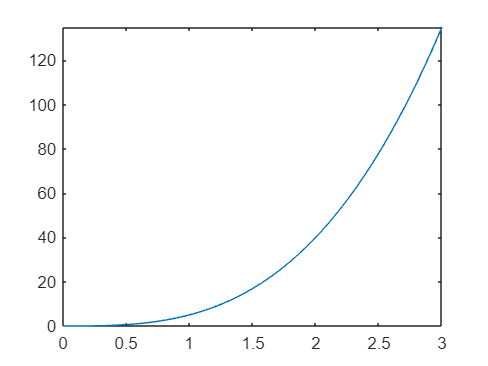

fplot(y,[0 3])

## Task 4

The definite integral finds the area between the curve and the x-axis from *a* to *b*.

area=∫baf(x)dx

To calculate the definite integral using `int`, specify the endpoints `a` and `b`.

`zArea` `=` `int``(``expn``,``t``,``[``a` `b``])`

Task

Find the area between the *x*-axis and the curve defined by `y` for `x` from 0 to 3. Store the result as `yArea`.

yArea=int(y,x,[0 3])

$$yArea = \frac{405}{4}$$

## Further Practice

A constant term is typically added to the result of an indefinite integral, since the derivative of any constant is zero.

∫2xdx=x2+C

Try differentiating then integrating an expression with a constant.

`expr` `=` `x``^``2+3`

`d` `=` `diff``(``expr``,``x``)`

`indef` `=` `int``(``d``,``x``)`

The `int` function does not include integration constants. 

Definite integrals, on the other hand, do not have an added constant term since they calculate a specific area.

`dArea` `=` `int``(``d``,``x``,``[``0` `1``])`

Here, the definite integral is exactly 1.

expr=x^2+3

$$expr = x^{2}+3$$

d=diff(expr,x)

$$d = 2\,x$$

indef=int(d,x)

$$indef = x^{2}$$

dArea=int(d,x,[0 1])

$$dArea = 1$$